# **Engineering Fluid Mechanics **

# **Term Project 1**

## **Pipe Structre Calculater 4**

2024/11/08 Uiseong An

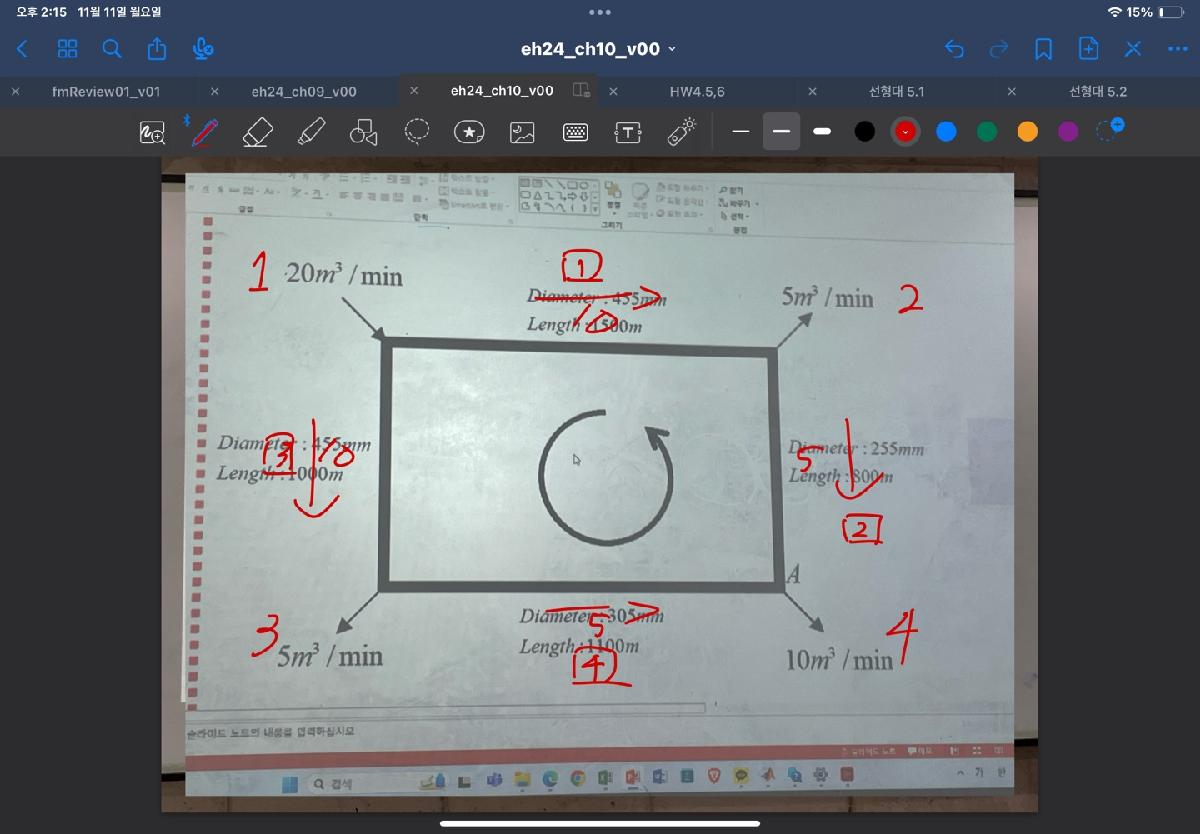

**Put information**

Number of pipe

n = 4;

Q information

Q1 = 10;
Q2 = 5;
Q3 = 10;
Q4 = 5;
Q5 = 0;
Q6 = 0;
Q7 = 0;
Q8 = 0;
Q9 = 0;
Q10 = 0;

Pipe Information

L1 = 1500;
D1 = 0.455;
L2 = 800;
D2 = 0.255;
L3 = 1000;
D3 = 0.455;
L4 = 1100;
D4 = 0.305;
L5 = 0;
D5 = 0;
L6 = 0;
D6 = 0;
L7 = 0;
D7 = 0;
L8 = 0;
D8 = 0;
L9 = 0;
D9 = 0;
L10 = 0;
D10 = 0;

area

A1 = pi * D1^2 / 4;
A2 = pi * D2^2 / 4;
A3 = pi * D3^2 / 4;
A4 = pi * D4^2 / 4;
A5 = pi * D5^2 / 4;
A6 = pi * D6^2 / 4;
A7 = pi * D7^2 / 4;
A8 = pi * D8^2 / 4;
A9 = pi * D9^2 / 4;
A10 = pi * D10^2 / 4;

#### **Basic set value**

Basic information

g = 9.81;
ccw = -1; %Counter clock wise

Kinemetic viscosty for Water ${20}^{\circ } C$

nu = 1 * 10^-6; %m

Commercial steel pipe for Sand-Graind Roughness, $k_s$

ks = 0.046 * 10^-3; %m

#### Find the correct anser to the roop

for i = 1:500
    V1 = abs(Q1 / A1); %abs()-> if V is (-)
    V2 = abs(Q2 / A2); %Re is the wrong anser
    V3 = abs(Q3 / A3); 
    V4 = abs(Q4 / A4); 
    %V5 = abs(Q5 / A5);
    %V6 = abs(Q6 / A6); 
    %V7 = abs(Q7 / A7); 
    %V8 = abs(Q8 / A8); 
    %V9 = abs(Q9 / A9); 
    %V10 = abs(Q10 / A10); 

    Re1 = V1 * D1 / nu;
    Re2 = V2 * D2 / nu;
    Re3 = V3 * D3 / nu;
    Re4 = V4 * D4 / nu;
    %Re5 = V5 * D5 / nu;
    %Re6 = V6 * D6 / nu;
    %Re7 = V7 * D7 / nu;
    %Re8 = V8 * D8 / nu;
    %Re9 = V9 * D9 / nu;
    %Re10 = V10 * D10 / nu;

    %Colebrook-White Formula
    f1 = 0.25 / (log10((ks/3.7/D1) + (5.74/(Re1^0.9))))^2;
    f2 = 0.25 / (log10((ks/3.7/D2) + (5.74/(Re2^0.9))))^2;
    f3 = 0.25 / (log10((ks/3.7/D3) + (5.74/(Re3^0.9))))^2;
    f4 = 0.25 / (log10((ks/3.7/D4) + (5.74/(Re4^0.9))))^2;
    %f5 = 0.25 / (log10((ks/3.7/D5) + (5.74/(Re5^0.9))))^2;
    %f6 = 0.25 / (log10((ks/3.7/D6) + (5.74/(Re6^0.9))))^2;
    %f7 = 0.25 / (log10((ks/3.7/D7) + (5.74/(Re7^0.9))))^2;
    %f8 = 0.25 / (log10((ks/3.7/D8) + (5.74/(Re8^0.9))))^2;
    %f9 = 0.25 / (log10((ks/3.7/D9) + (5.74/(Re9^0.9))))^2;
    %f10 = 0.25 / (log10((ks/3.7/D10) + (5.74/(Re10^0.9))))^2;

    %Darcy-Eeisbach Equation
    hf1 = f1 * L1 * V1^2 / D1 / 2 / g;
    hf2 = f2 * L2 * V2^2 / D2 / 2 / g; % ccw -> Opposite direction
    hf3 = f3 * L3 * V3^2 / D3 / 2 / g;
    hf4 = f4 * L4 * V4^2 / D4 / 2 / g;
    %hf5 = f5 * L5 * V5^2 / D5 / 2 / g;
    %hf6 = f6 * L6 * V6^2 / D6 / 2 / g;
    %hf7 = f7 * L7 * V7^2 / D7 / 2 / g;
    %hf8 = f8 * L8 * V8^2 / D8 / 2 / g;
    %hf9 = f9 * L9 * V9^2 / D9 / 2 / g;
    %hf10 = f10 * L10 * V10^2 / D10 / 2 / g;


    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %        set loop flow       %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Design the loop flow by considering Q 
    %related to the direction of the loop.

    x = 2; %Usely 2 in Darcy-Weisbach eq

    %Loop 1 
    hf_L1 = ccw*hf1 + ccw*hf2 + hf3 + hf4;
    hf_Q_L1 = hf1/Q1 + hf2/Q2 + hf3/Q3 + hf4/Q4;
    delta_L1 = - hf_L1 / hf_Q_L1 / x;

    % %Loop 2
    % hf_L2 = hf2 + hf3;
    % hf_Q_L2 = hf2/Q2 + hf3/Q3;
    % delta_L2 = - hf_L2 / hf_Q_L2 / x;
    % 
    % %Loop 3 
    % hf_L3 = hf3 + hf2;
    % hf_Q_L3 = hf1/Q1 + hf2/Q2;
    % delta_L3 = - hf_L3 / hf_Q_L3 / x;
    % 
    % %Loop 4
    % hf_L4 = hf2 + hf3;
    % hf_Q_L4 = hf2/Q2 + hf3/Q3;
    % delta_L4 = - hf_L4 / hf_Q_L4 / x;
    % 
    % %Loop 5 
    % hf_L5 = hf1 + hf2;
    % hf_Q_L5 = hf1/Q1 + hf2/Q2;
    % delta_L5 = - hf_L5 / hf_Q_L5 / x;
    % 
    % %Loop 6
    % hf_L6 = hf2 + hf3;
    % hf_Q_L6 = hf2/Q2 + hf3/Q3;
    % delta_L6 = - hf_L6 / hf_Q_L6 / x;
    % 
    % %Loop 7 
    % hf_L7 = hf1 + hf2;
    % hf_Q_L7 = hf1/Q1 + hf2/Q2;
    % delta_L7 = - hf_L7 / hf_Q_L7 / x;
    % 
    % %Loop 8
    % hf_L8 = hf2 + hf3;
    % hf_Q_L8 = hf2/Q2 + hf3/Q3;
    % delta_L8 = - hf_L8 / hf_Q_L8 / x;
    % 
    % %Loop 9 
    % hf_L9 = hf1 + hf2;
    % hf_Q_L9 = hf1/Q1 + hf2/Q2;
    % delta_L9 = - hf_L9 / hf_Q_L9 / x;
    % 
    % %Loop 10
    % hf_L10 = hf2 + hf3;
    % hf_Q_L10 = hf2/Q2 + hf3/Q3;
    % delta_L10 = - hf_L10 / hf_Q_L10 / x;


    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %         set Q flow         %
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    Q1 = abs(ccw*Q1 + delta_L1);
    Q2 = abs(ccw*Q2 + delta_L1);
    Q3 = Q3 + delta_L1;
    Q4 = Q4 + delta_L1;
    % Q5 = Q5 + ccw*delta_L5;
    % Q6 = Q6 + ccw*delta_L6;
    % Q7 = Q7 + ccw*delta_L7;
    % Q8 = Q8 + ccw*delta_L8;
    % Q9 = Q9 + ccw*delta_L9;
    % Q10 = Q10 + ccw*delta_L10;


   %  if abs(delta_L1) < 10^-3 && abs(delta_L2) < 10^-3 && abs(delta_L3) < 10^-3 && ...
   % abs(delta_L4) < 10^-3 && abs(delta_L5) < 10^-3 && abs(delta_L6) < 10^-3 && ...
   % abs(delta_L7) < 10^-3 && abs(delta_L8) < 10^-3 && abs(delta_L9) < 10^-3 && ...
   % abs(delta_L10) < 10^-3

     if abs(delta_L1) < 10^-3
        %disp(['Re1 =  ', num2str(Re1, '%.4e')]);
        %disp(['Re2 =  ', num2str(Re2, '%.4e')]);

        disp(['Delta1 =  ', num2str(delta_L1, '%.4e')]);
        % disp(['Delta2 =  ', num2str(delta_L2, '%.4e')]);
        % disp(['Delta3 =  ', num2str(delta_L3, '%.4e')]);
        % disp(['Delta4 =  ', num2str(delta_L4, '%.4e')]);
        % disp(['Delta5 =  ', num2str(delta_L5, '%.4e')]);
        % disp(['Delta6 =  ', num2str(delta_L6, '%.4e')]);
        % disp(['Delta7 =  ', num2str(delta_L7, '%.4e')]);
        % disp(['Delta8 =  ', num2str(delta_L8, '%.4e')]);
        % disp(['Delta9 =  ', num2str(delta_L9, '%.4e')]);
        % disp(['Delta10 =  ', num2str(delta_L10, '%.4e')]);

        disp(['Q1 =  ', num2str(Q1, '%.4e')]);
        disp(['Q2 =  ', num2str(Q2, '%.4e')]);
        disp(['Q3 =  ', num2str(Q3, '%.4e')]);
        disp(['Q4 =  ', num2str(Q4, '%.4e')]);
        % disp(['Q5 =  ', num2str(Q5, '%.4e')]);
        % disp(['Q6 =  ', num2str(Q6, '%.4e')]);
        % disp(['Q7 =  ', num2str(Q7, '%.4e')]);
        % disp(['Q8 =  ', num2str(Q8, '%.4e')]);
        % disp(['Q9 =  ', num2str(Q9, '%.4e')]);
        % disp(['Q10 =  ', num2str(Q10, '%.4e')]);

        break;
     end
       
end

ans = 20

ans = 20

ans = 20

Delta1 =  6.4159e-05


Q1 =  9.1971e+00


Q2 =  4.1971e+00


Q3 =  1.0803e+01


Q4 =  5.8029e+00
